clc; clear all; close all;

**Task 2: Find parameter solutions for the following scenario**

**Scenario 3:** The system shows chaotic behavior and the lynx population peaks twice within the 200-months period. What makes this behavior chaotic and not oscillating or random? Hint: Chaotic behavior is deterministic, sensitive to initial conditions, bounded and irregular.

Chaotic behavior is deterministic, meaning it is not random. Instead of a cloud of random points as is visible in stochastic (random) behavior, with chaotic behavior there is a definitive shape. Due to its deterministic behavior, the trajectories seen in the time-series and state-space of chaotic simulations are complex compared to that of stochastic behvaior. 

Chaotic behavior is sensitive to initial conditions in that a small change results in a comparatively larger diversion or unpredictable change in the simulation; ie depicting the "butterfly effect." 

Chaotic behavior is irregular, but bounded within certain limits. Due to being confined, it appears to osciliate and exhibit some period. However, it maintains an unpredictable randomness with each cycle within the non-repeated time series, unlike that of oscillating and periodic behavior. 

**Simulation settings:**

**Timespan**: In all scenarios, simulate from 0 to 200 months.

t0 = 0;                 	% Start time of simulation [in months]
tfinal = 200;               % End time of simulation [in months]
tspan = [t0 tfinal];        % Time span defined by the start and end times of the simulation [in months]

**Initial population sizes:**

y0 = [0.8 0.2 8]            % Initial state [plants hares lynx] at t=0, between 0.1-10 for each

y0 =     0.8000    0.2000    8.0000


y0_test = [0.81 0.21 8.01]  % Slight variation of initial population to check if it is chaotic

y0_test =     0.8100    0.2100    8.0100


**Parameter values:**

a1 = 5                      % Hare predation success rate ("how likely the plant dies if it meets a hare"), between 1-10

a1 = 5

b1 = 3                      % Hare population growth rate due to predation on plants ("how much food a hare gets out of eating plants"), between 1-10

b1 = 3

d1 = 0.45                   % Hare per capita death rate, between 0.1-1

d1 = 0.4500

a2 = 0.1                    % Lynx predation success rate ("how likely the hare dies if it meets a lynx"), between 0.1-1

a2 = 0.1000

b2 = 2                      % Lynx population growth rate due to predation on hares ("how much food a lynx gets out of eating hares"), between 1-10

b2 = 2

d2 = 0.01                   % Lynx per capita death rate, between 0.01-1

d2 = 0.0100

**Model simulation**

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);            % Solving of the Plant-Hare-Lynx 3-species model

[t,y_test] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0_test);  % Test of population variation to prove chaotic scenario

**Population over time plot**

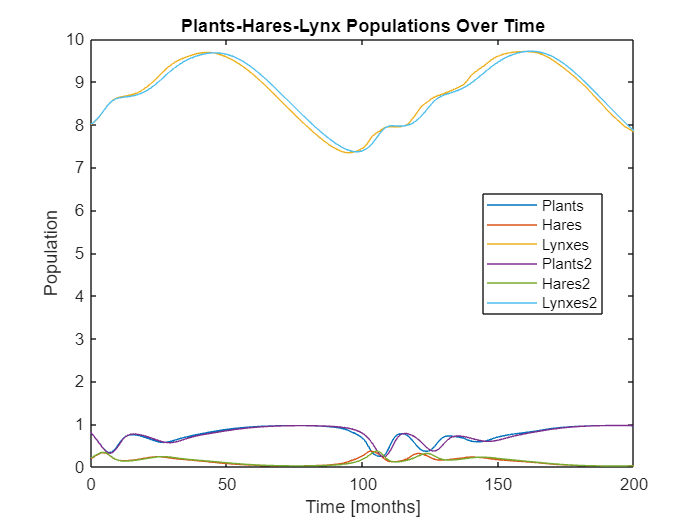

figure("Name",'Plants-Hares-Lynx')
plot(t,y)                                           % Solution plot
title('Plants-Hares-Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
hold on
plot(t,y_test)                                      % Plot of the test in addition to the solution plot
legend('Plants','Hares','Lynxes','Plants2','Hares2','Lynxes2','Location','Best')

**State space plot**

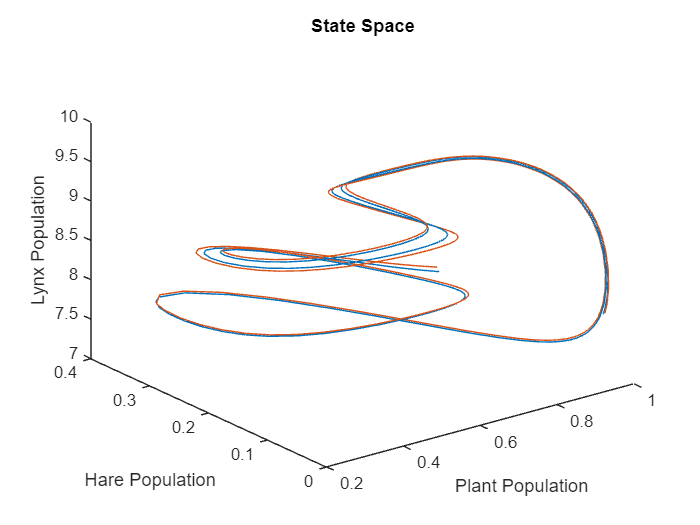

figure("Name",'State Space')
plot3(y(:,1),y(:,2),y(:,3));                        % Solution plot
title('State Space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')
hold on
plot3(y_test(:,1),y_test(:,2),y_test(:,3));         % Plot of the test in addition to the solution plot

The time-series and state-space plots exhibit the non-repeating and complex trajectories that are hallmarks of chaos. Furthermore, plotting the slight variation of the initial populations on top of the same graph clearly shows the large diversion of the new function caused by a very small (0.01) difference of initial conditions; confirming the butterfly effect.

function dydt = plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2)

dydt = zeros(3,1);

% y(1) is X, number of plants
% y(2) is Y, number of hares
% y(3) is Z, number of lynxes

% Equations describing the rate of change population of three species system
dydt(1) = y(1)*(1-y(1)) - ((a1*y(1))/(1+b1*y(1)))*y(2);                          %Plants
dydt(2) = ((a1*y(1))/(1+b1*y(1)))*y(2)-d1*y(2)-(a2*y(2)/(1+b2*y(2)))*y(3);       %Hares
dydt(3) = (a2*y(2)/(1+b2*y(2)))*y(3) - d2*y(3);                                  %Lynxes

end
